依赖[统一实验分析作图v17.2.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Similar activity in MOp Learned_task_A and Transfer_task_B

DataSet=TransferLearning.FullCalcium;

声光迁移

ALCalcium=DataSet.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'声光HitMiss'),UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median);

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);

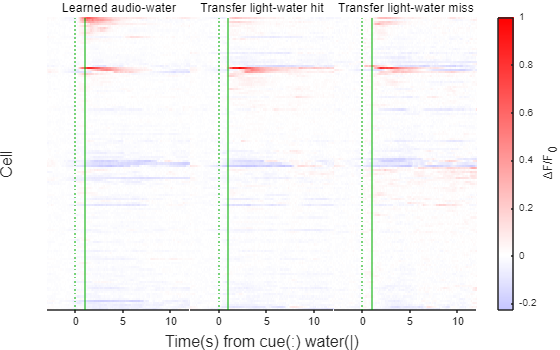

Layout=TransferLearning.BasicHeatmap(UniExp.HeatmapSort(ALCalcium).NTATS{:,:,["Learned_audio_water","Transfer_light_water_hit","Transfer_light_water_miss"]},["Learned audio-water","Transfer light-water hit","Transfer light-water miss"],Colors,false);
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('AudioLightHitMiss.svg'),'-dsvg');